## Data load

time4PreTrainStart = tic;

expMatrix = readtable('TCGA-GBM.htseq_counts.txt', 'ReadRowNames', true);

mutMatrix = readtable('GBM_mc3_gene_level.txt', 'ReadRowNames', true);

PPI = readtable('STRINGv10.txt', 'ReadVariableNames', false);
PPI.Properties.VariableNames = {'Gene1', 'Gene2', 'Weight'};
Pathway = readtable('kegg_pathways_aggravated.txt', 'ReadVariableNames', false, 'Delimiter', '\t');

expMatrix.Properties.RowNames = strtrim(expMatrix.Properties.RowNames); 
expMatrix = expMatrix(~contains(expMatrix.Properties.RowNames, {' ', '.'}), :);
expMatrix = expMatrix(~cellfun('isempty', expMatrix.Properties.RowNames), :);

newColNames = cellfun(@(x) x(1:min(15, length(x))), expMatrix.Properties.VariableNames ...
    , 'UniformOutput', false);

[~, uniqueIdx] = unique(newColNames, 'stable');
expMatrix = expMatrix(:, uniqueIdx);
expMatrix.Properties.VariableNames = newColNames(uniqueIdx);

numSamples = size(mutMatrix, 2);
mutationFrequency = sum(mutMatrix{:,:}, 2) / numSamples;
mutMatrix = mutMatrix(mutationFrequency >= 0.02, :);
sampleMutationCounts = sum(mutMatrix{:,:}, 1);
mutMatrix = mutMatrix(:, sampleMutationCounts >= 3); 
PPI = PPI(PPI{:, 3} >= 0.2, :);

commonSamples = intersect(expMatrix.Properties.VariableNames, mutMatrix.Properties.VariableNames);
mutMatrix = mutMatrix(:, commonSamples);
expMatrix = expMatrix(:, commonSamples);

commonGenes = intersect(expMatrix.Properties.RowNames, mutMatrix.Properties.RowNames);
expMatrix = expMatrix(commonGenes, :);
mutMatrix = mutMatrix(commonGenes, :);

expMatrixZ = zscore(expMatrix{:,:}, 0, 2);
numSamples = size(expMatrix, 2);
diffGenes = cell(numSamples, 1);
for i = 1:numSamples
    sampleZ = expMatrixZ(:, i);
    diffGenes{i} = expMatrix.Properties.RowNames(abs(sampleZ) > 0.5);
end

time4PreTrain = toc(time4PreTrainStart);
disp(['Data import and processing time: ', num2str(time4PreTrain)]);

Data import and processing time: 10.5562


PathwayNames = Pathway.Var1;
PathwayGenes = cellfun(@(x) strsplit(x, ','), Pathway.Var4, 'UniformOutput', false);
load("CancerDriverGenesGBM_20240621_222151.mat");

## Construct Sample-specific hypergraph model

tic;

[numGenes, numSamples] = size(mutMatrix);

patientHypergraph = cell(numSamples, 1);

for sampleIdx = 1:numSamples
    sampleName = mutMatrix.Properties.VariableNames{sampleIdx};
    mutGenes = mutMatrix.Properties.RowNames(mutMatrix{:, sampleIdx} == 1);
    DEGs = diffGenes{sampleIdx};
    hyperEdges = {};

    for geneIdx = 1:length(mutGenes)
        mutGene = mutGenes{geneIdx};
        pathwayIdx = cellfun(@(x) ismember(mutGene, x), PathwayGenes);
        pathwaysWithMutGene = PathwayNames(pathwayIdx);
        for pathIdx = 1:length(pathwaysWithMutGene)
            pathwayGenes = PathwayGenes{pathIdx};

            relevantGenes = unique([mutGene; DEGs]);
            commonGenes = intersect(pathwayGenes, relevantGenes);
            if length(commonGenes) > 1
                hyperEdges{end+1} = commonGenes;
            end
        end
    end

    patientHypergraph{sampleIdx} = hyperEdges;
end

time4ConstructHOI = toc;
fprintf('Time to construct hypergraph models: %.2f seconds\n', time4ConstructHOI);

Time to construct hypergraph models: 10.06 seconds


## Propagation on SIR model 

betaValues = linspace(0.001, 0.02, 20); 
gammaValues = 0.1:0.1:1; 
Yita = 0.2;
T = 5;
topN = 8;
numSimulations = 50; 
SampleTarget = 4;
targetHypergraph = patientHypergraph{SampleTarget};
driveGenes = rankForSamples{SampleTarget}(:, 1);

mutGenes = mutMatrix.Properties.RowNames(mutMatrix{:, sampleIdx} == 1);
diffGenesSet = diffGenes{SampleTarget};

allNodes = {};
for i = 1:length(targetHypergraph)
    allNodes = union(allNodes, targetHypergraph{i});
end

avgRouValues_driveGenes = zeros(length(gammaValues), length(betaValues));
avgRouValues_mutMatrix = zeros(length(gammaValues), length(betaValues)); 
avgRouValues_diffGenes = zeros(length(gammaValues), length(betaValues));

for gIdx = 1:length(gammaValues)
    gamma = gammaValues(gIdx);

    rouValues_driveGenes = zeros(numSimulations, length(betaValues));
    rouValues_mutMatrix = zeros(numSimulations, length(betaValues));
    rouValues_diffGenes = zeros(numSimulations, length(betaValues));

    for sim = 1:numSimulations
        initialInfected_driveGenes = driveGenes(1:topN);
        initialInfected_mutMatrix = datasample(mutGenes, topN, 'Replace', false);
        initialInfected_diffGenes = datasample(diffGenesSet, topN, 'Replace', false);
        rouValues_driveGenes_sim = zeros(length(betaValues), 1);
        rouValues_mutMatrix_sim = zeros(length(betaValues), 1);
        rouValues_diffGenes_sim = zeros(length(betaValues), 1);

        for bIdx = 1:length(betaValues)
            beta = betaValues(bIdx);

            nodeStates_driveGenes = containers.Map(allNodes, zeros(length(allNodes), 1));
            for i = 1:length(initialInfected_driveGenes)
                nodeStates_driveGenes(initialInfected_driveGenes{i}) = 1;
            end
            nodeStates_mutMatrix = containers.Map(allNodes, zeros(length(allNodes), 1));
            for i = 1:length(initialInfected_mutMatrix)
                nodeStates_mutMatrix(initialInfected_mutMatrix{i}) = 1;
            end

            nodeStates_diffGenes = containers.Map(allNodes, zeros(length(allNodes), 1));
            for i = 1:length(initialInfected_diffGenes)
                nodeStates_diffGenes(initialInfected_diffGenes{i}) = 1;
            end
            for t = 1:T
                newInfected_driveGenes = {};
                for i = 1:length(targetHypergraph)
                    hyperedge = targetHypergraph{i};
                    infectedCount = sum(cell2mat(values(nodeStates_driveGenes, hyperedge)) == 1);
                    recoveredCount = sum(cell2mat(values(nodeStates_driveGenes, hyperedge)) == 2);
                    totalNodes = length(hyperedge);
                    rou = (infectedCount + recoveredCount) / totalNodes;

                    if rou > Yita
                        for j = 1:length(hyperedge)
                            node = hyperedge{j};
                            if nodeStates_driveGenes(node) == 0 % S-state
                                if rand < beta
                                    newInfected_driveGenes{end+1} = node;
                                end
                            elseif nodeStates_driveGenes(node) == 1 % I-state
                                if rand < gamma
                                    nodeStates_driveGenes(node) = 2; % R-state
                                end
                            end
                        end
                    end
                end

                for k = 1:length(newInfected_driveGenes)
                    nodeStates_driveGenes(newInfected_driveGenes{k}) = 1;
                end
            end

            infectedCount = sum(cell2mat(values(nodeStates_driveGenes)) == 1);
            recoveredCount = sum(cell2mat(values(nodeStates_driveGenes)) == 2);
            rouValues_driveGenes_sim(bIdx) = (infectedCount + recoveredCount) / length(allNodes);

            for t = 1:T
                newInfected_mutMatrix = {};
                for i = 1:length(targetHypergraph)
                    hyperedge = targetHypergraph{i};
                    infectedCount = sum(cell2mat(values(nodeStates_mutMatrix, hyperedge)) == 1);
                    recoveredCount = sum(cell2mat(values(nodeStates_mutMatrix, hyperedge)) == 2);
                    totalNodes = length(hyperedge);
                    rou = (infectedCount + recoveredCount) / totalNodes;

                    if rou > Yita
                        for j = 1:length(hyperedge)
                            node = hyperedge{j};
                            if nodeStates_mutMatrix(node) == 0 % S-state
                                if rand < beta
                                    newInfected_mutMatrix{end+1} = node;
                                end
                            elseif nodeStates_mutMatrix(node) == 1 % I-state
                                if rand < gamma
                                    nodeStates_mutMatrix(node) = 2; % R-state
                                end
                            end
                        end
                    end
                end

                for k = 1:length(newInfected_mutMatrix)
                    nodeStates_mutMatrix(newInfected_mutMatrix{k}) = 1;
                end
            end

            infectedCount = sum(cell2mat(values(nodeStates_mutMatrix)) == 1);
            recoveredCount = sum(cell2mat(values(nodeStates_mutMatrix)) == 2);
            rouValues_mutMatrix_sim(bIdx) = (infectedCount + recoveredCount) / length(allNodes);

            for t = 1:T
                newInfected_diffGenes = {};
                for i = 1:length(targetHypergraph)
                    hyperedge = targetHypergraph{i};
                    infectedCount = sum(cell2mat(values(nodeStates_diffGenes, hyperedge)) == 1);
                    recoveredCount = sum(cell2mat(values(nodeStates_diffGenes, hyperedge)) == 2);
                    totalNodes = length(hyperedge);
                    rou = (infectedCount + recoveredCount) / totalNodes;

                    if rou > Yita
                        for j = 1:length(hyperedge)
                            node = hyperedge{j};
                            if nodeStates_diffGenes(node) == 0 % S-state
                                if rand < beta
                                    newInfected_diffGenes{end+1} = node; 
                                end
                            elseif nodeStates_diffGenes(node) == 1 % I-state
                                if rand < gamma
                                    nodeStates_diffGenes(node) = 2; % R-state
                                end
                            end
                        end
                    end
                end

                for k = 1:length(newInfected_diffGenes)
                    nodeStates_diffGenes(newInfected_diffGenes{k}) = 1;
                end
            end

            infectedCount = sum(cell2mat(values(nodeStates_diffGenes)) == 1);
            recoveredCount = sum(cell2mat(values(nodeStates_diffGenes)) == 2);
            rouValues_diffGenes_sim(bIdx) = (infectedCount + recoveredCount) / length(allNodes);
        end
        rouValues_driveGenes(sim, :) = rouValues_driveGenes_sim;
        rouValues_mutMatrix(sim, :) = rouValues_mutMatrix_sim;
        rouValues_diffGenes(sim, :) = rouValues_diffGenes_sim;
    end


    avgRouValues_driveGenes(gIdx, :) = mean(rouValues_driveGenes, 1);
    avgRouValues_mutMatrix(gIdx, :) = mean(rouValues_mutMatrix, 1);
    avgRouValues_diffGenes(gIdx, :) = mean(rouValues_diffGenes, 1); 
    gIdx
end

gIdx = 1

gIdx = 2

figure;

for gIdx = 1:length(gammaValues)
    subplot(2, 5, gIdx);
    hold on;

    plot(betaValues/gammaValues(gIdx), avgRouValues_driveGenes(gIdx, :), '-o', 'Color', 'r');
    plot(betaValues/gammaValues(gIdx), avgRouValues_mutMatrix(gIdx, :), '-o', 'Color', 'g');
    plot(betaValues/gammaValues(gIdx), avgRouValues_diffGenes(gIdx, :), '-o', 'Color', 'b');

    hold off;
    xlabel('\lambda (Eff Sprding Prob)');
    ylabel('\rho (Inf + Recvy Rate)');
    title(sprintf('Gamma = %.1f', gammaValues(gIdx)));
    grid on;
end


## Plot

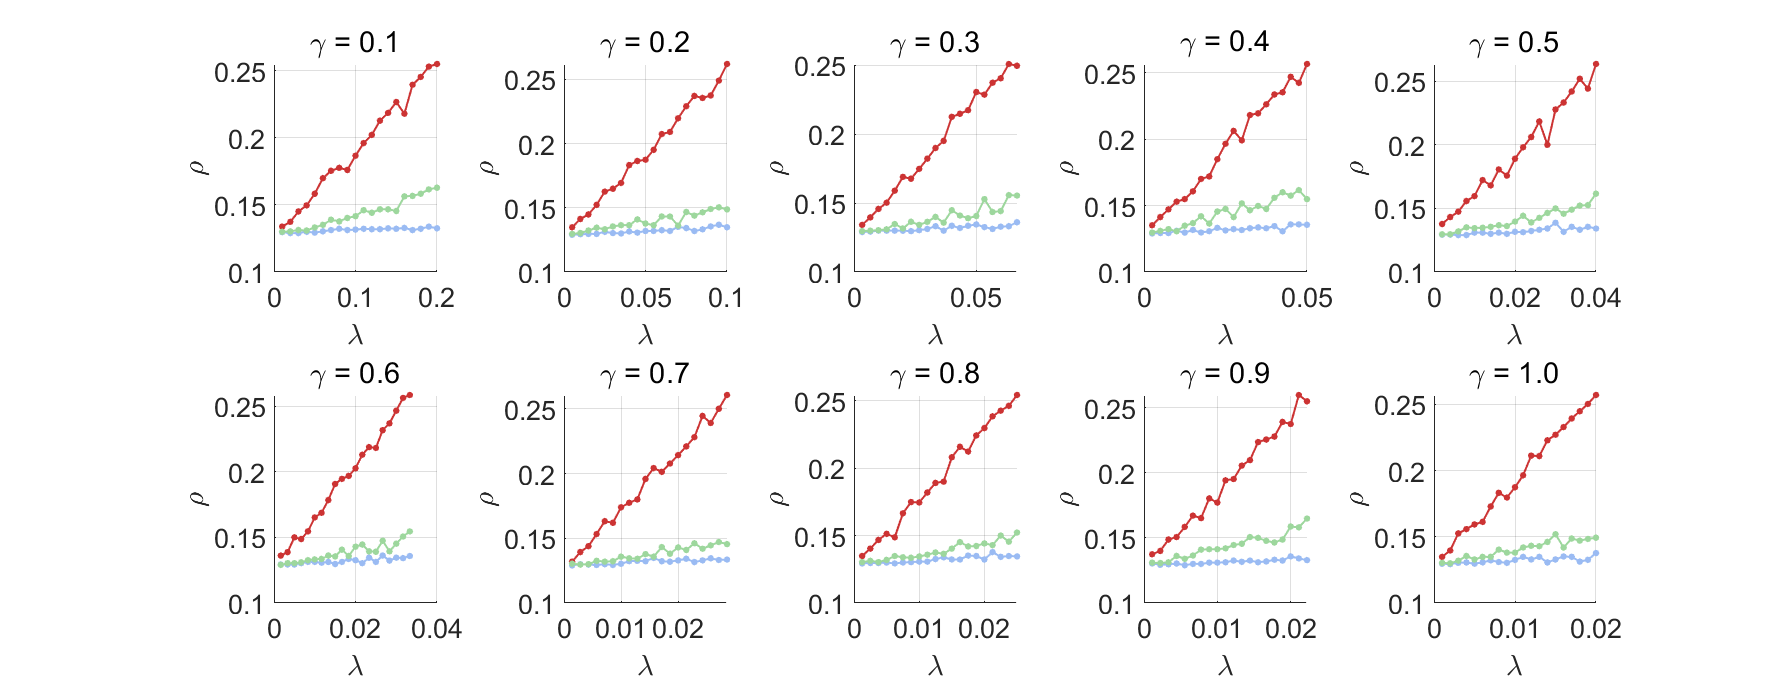

figure;

for gIdx = 1:length(gammaValues)
    subplot(2, 5, gIdx);
    hold on;
    plot(betaValues/gammaValues(gIdx), avgRouValues_driveGenes(gIdx, :), '-o', 'Color', [0.8, 0.2, 0.2], 'LineWidth', 1.5, 'MarkerSize', 3.5, 'MarkerFaceColor', [0.8, 0.2, 0.2]);
    plot(betaValues/gammaValues(gIdx), avgRouValues_mutMatrix(gIdx, :), '-o', 'Color', '#9ABBF3', 'LineWidth', 1.5, 'MarkerSize', 3.5, 'MarkerFaceColor', '#9ABBF3');
    plot(betaValues/gammaValues(gIdx), avgRouValues_diffGenes(gIdx, :), '-o', 'Color', '#9DD79D', 'LineWidth', 1.5, 'MarkerSize', 3.5, 'MarkerFaceColor', '#9DD79D');

    hold off;

    xlabel('\lambda', 'FontSize', 16);
    ylabel('\rho', 'FontSize', 16);
    title(sprintf('\\gamma = %.1f', gammaValues(gIdx)), 'FontSize', 20, 'Interpreter', 'tex');
    set(gca, 'FontSize', 20);
    grid on;
end

set(gcf, 'Position', [50, 50, 1780, 700]);
print('HOI', '-dpng', '-r300');

## 保存数据

% 
% currentDateTime = datestr(now, 'yyyymmdd_HHMMSS');
% fileName = ['3LinesForSIR_', currentDateTime, '.mat'];
%
% 
% save(fileName, 'avgRouValues_driveGenes', 'avgRouValues_mutMatrix', 'avgRouValues_diffGenes', ...
%     'SampleTarget','targetHypergraph',...
%     'gammaValues','betaValues','gIdx');